Lös den partiella differentialekvationen med randvillkor och initialvillkor:

$\frac{\partial }{\partial t}u=\frac{\partial^2 }{\partial x^2 }u+2\frac{\partial }{\partial x}u$, $u\left(x,0\right)=\frac{1}{2}\sin \left(2\pi x\right)e^{-x}$, $u\left(0,t\right)\;=\;u\left(1,t\right)=0$.

Använd finita differensmetoden och centrala differenser.

Central differens för andraderivata: ${y^{\prime } }^{\prime } \left(x_i \right)\approx \frac{y\left(x_{i+1} \right)-2y\left(x_i \right)+y\left(x_{i-1} \right)}{h^2 }$.

Central differens för förstaderivata: $y^{\prime } \left(x_i \right)\approx \frac{y\left(x_{i+1} \right)-y\left(x_{i-1} \right)}{2h}$.

Analytisk lösning är $u\left(x,t\right)=\frac{1}{2}e^{-\left(1+4\pi^2 \right)t} \sin \left(2\pi x\right)e^{-x}$.

clear all
close all

% Antal delintervall i rummet
N=100

N = 100


% Randvillkor
w0=0; 
wN=0; 

% steglängd h
h=1/N;
% vektor xv (med ränderna inkluderade) 
% och xvint (för inre punkter)
xv=(0:N)'*h;
xvint=(1:N-1)'*h;
% Sätt upp systemmatrisen med eye (enhetsmatris) 
% och diag (diagonalmatris)
% help elmat
A=-(2/h^2)*eye(N-1); 
A=A+diag((1/h^2-1/h)*ones(N-2,1),-1)+diag((1/h^2+1/h)*ones(N-2,1),1);

% Högerledet
b=zeros(N-1,1); 
b(1)=b(1)-w0; 
b(end)=b(end)-wN; 

% Tidsstegning:

% Antal tidssteg
% faktor = 1.1;
%dt = faktor*1.25e-3; % N = 20
%dt = faktor*2e-4; % N = 50
dt = 5e-5; % N = 100
T = 0.1;
M = floor(T/dt);

% Beräkna spektralradien för Eulers metod
C = speye(N-1) + dt*A;
%max(abs(eig(dt*A)))
spektralradie_EF = max(abs(eig(C)))

spektralradie_EF = 0.9995


% Euler framåt
U_EF = 1/2*sin(2*pi*xvint).*exp(-xvint);
U_EF_MAT = sparse(N-1,M);
U_EF_MAT(:,1) = U_EF;

for i=1:M
    U_EF_MAT(:,i+1) = U_EF_MAT(:,i) + dt*A*U_EF_MAT(:,i);
end



% Crank Nicolson
U_CN = 1/2*sin(2*pi*xvint).*exp(-xvint);
U_CN_MAT = sparse(N-1,M);
U_CN_MAT(:,1) = U_CN;

% u^n+1 = u^n + dt/2*A*u^n + dt/2*A*u^n+1
% (I-dt/2*A)u^n+1 = (I+dt/2*A)u^n
C = speye(N-1) + dt/2*A;
B = speye(N-1) - dt/2*A;
Binv = inv(B);
spektralradie_CN = max(abs(eig(Binv*C)))

spektralradie_CN = 0.9995

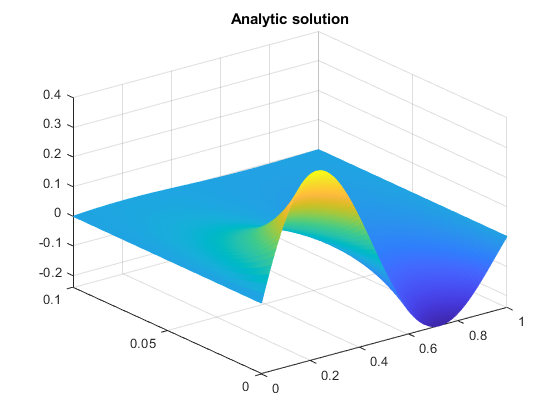


for j=1:M
    U_CN_MAT(:,j+1) = B\(C*U_CN_MAT(:,j));
end


tvec = [0:dt:T];
[X,T] = meshgrid(xv,tvec);
u_ana = @(x,t) 1/2*exp(-(1+4*pi^2)*t).*sin(2*pi*x).*exp(-x);
U_ANALYTIC = u_ana(X,T);
figure
mesh(X,T,U_ANALYTIC)
title('Analytic solution')

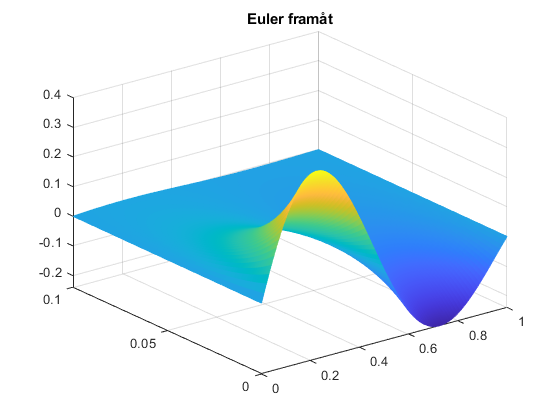


% Plotta Euler framåt
U_EF_MAT = [u_ana(0,tvec); U_EF_MAT; u_ana(1,tvec);]';
figure
mesh(X,T,U_EF_MAT)
title('Euler framåt')

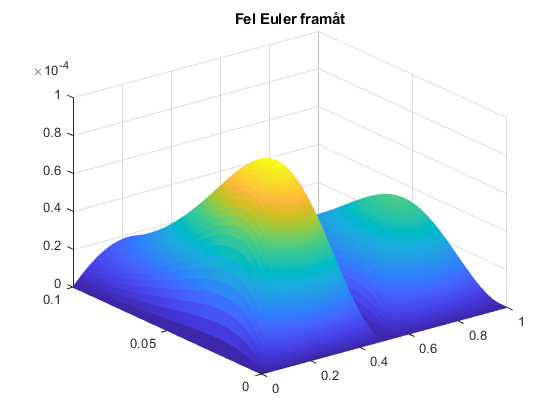


figure
mesh(X,T,abs(U_EF_MAT-U_ANALYTIC))
title('Fel Euler framåt')

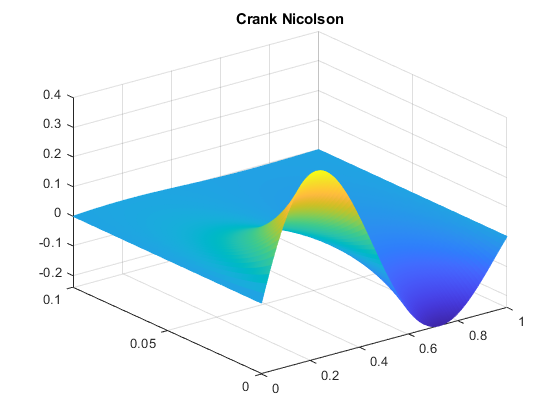



% Plotta Crank Nicolson
U_CN_MAT = [u_ana(0,tvec); U_CN_MAT; u_ana(1,tvec);]';
figure
mesh(X,T,U_CN_MAT)
title('Crank Nicolson')

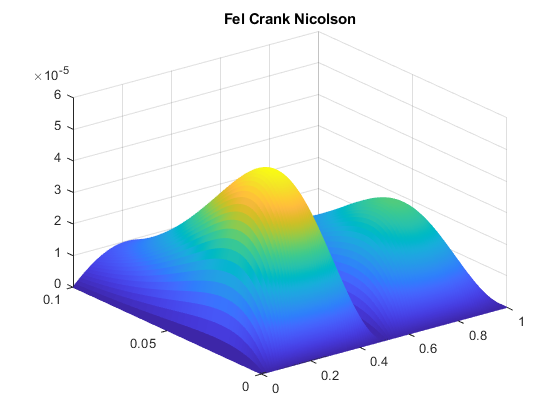


figure
mesh(X,T,abs(U_CN_MAT-U_ANALYTIC))
title('Fel Crank Nicolson')


maxfel_EF = max(max(abs(U_EF_MAT-U_ANALYTIC)))

maxfel_EF = 9.3426e-05

maxfel_CN = max(max(abs(U_CN_MAT-U_ANALYTIC)))

maxfel_CN = 5.3392e-05